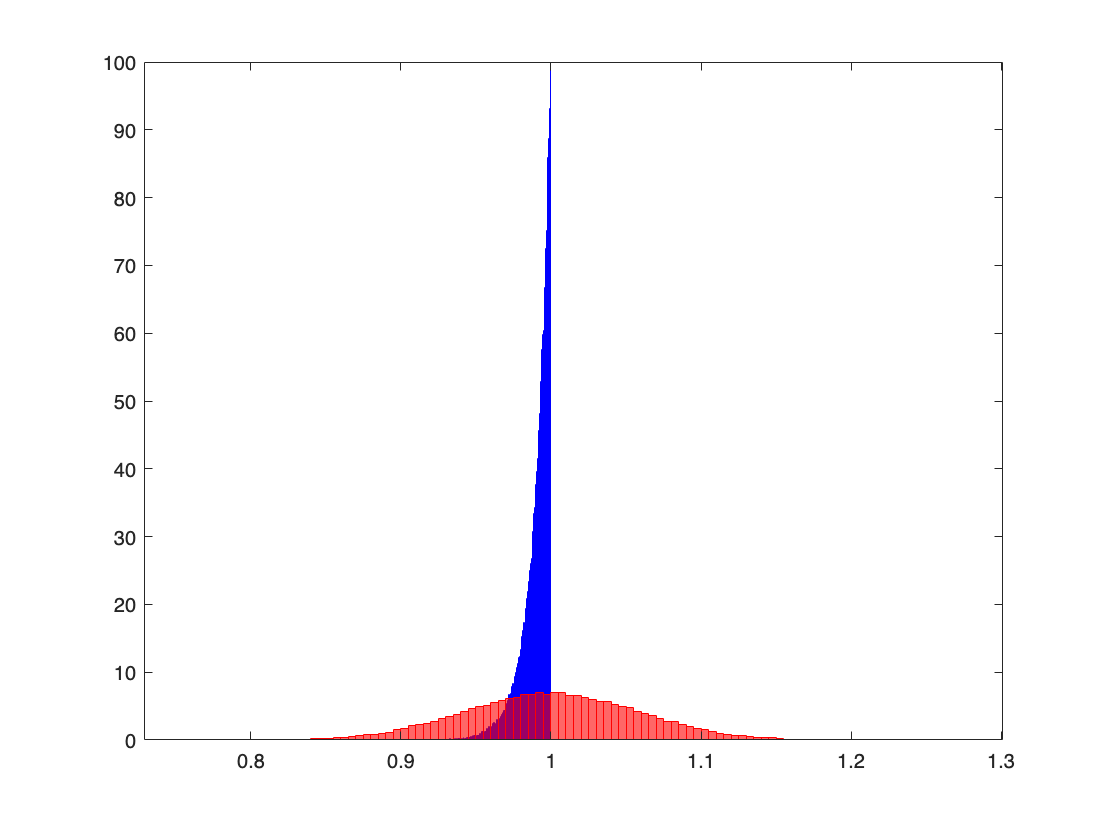

% Setting up parameters of Monte Carlo simulation
% ---------------------------------------
clc
clear all
clf

numMonteCLoops = 1E5; % Number of Monte Carlo Loops
theta = 1; % True value of the parameter
N = 100; % Number of observations
% ---------------------------------------


% Initializing variable for stability
estimate1 = ones(1,numMonteCLoops)*NaN;
estimate2 = ones(1,numMonteCLoops)*NaN;
for MC=1:numMonteCLoops
    x = rand(theta, N);
    estimate1(MC) = max(x);

    A_est_mean = mean(x)*2;
    estimate2(MC) = A_est_mean;
end


hist1 = histogram(estimate1, 'Normalization', 'pdf', 'EdgeColor', 'b', 'FaceColor', 'b', 'DisplayName', 'Estimate 1');
hold on;
histogram(estimate2, 'Normalization', 'pdf', 'EdgeColor', 'r', 'FaceColor', 'r', 'DisplayName', 'Estimate 2');

legend('show');
hold on;

mean_est1 = mean(estimate1)

mean_est1 = 0.9901

mean_est2 = mean(estimate2)

mean_est2 = 0.9997

std_est2 = std(estimate2)

std_est2 = 0.0577

By the looks of the expected values of the estimates which are very close to the true value, it is safe to say estimate 1 is biased where as estimate 2 is unbiased.

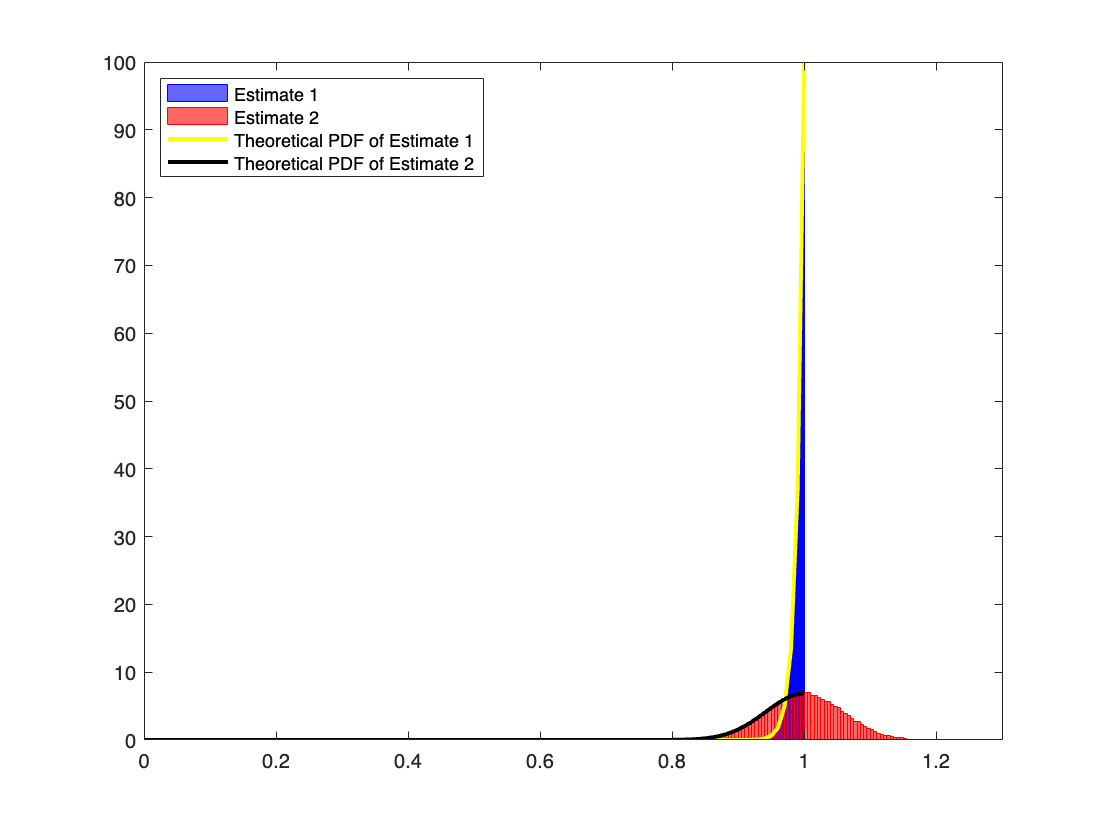

% Plot theoretical value of estimate 1 
% Proof of theoretical PDF is provided in the report. 
x = 0:0.01:1;
theoPDF_est1 = N * x.^(N - 1) / theta^N;
theoPDF_est1_normalized =max(estimate1) * theoPDF_est1 / max(theoPDF_est1);
plot(x, theoPDF_est1, 'LineWidth', 2, 'DisplayName', 'Theoretical PDF of Estimate 1','Color', 'yellow');
hold on;

sigma_est2 = std(estimate2);
mu = mean(estimate2);
theoPDF_est2 = 1 / (sigma_est2 * sqrt(2*pi)) * exp(-0.5 * ((x - mu) / sigma_est2).^2);
plot(x, theoPDF_est2, 'LineWidth', 2, 'DisplayName', 'Theoretical PDF of Estimate 2','Color', 'black');

legend('Location', 'northwest');

legend('show');